close all; clear; clc;

# 4 bat full run 10 min (P80 motor)

**file name**: P80_4bat_10min_20181106.mlx

**keywords:** 

**date of test:** 20180928

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3] 
% Record this in the notes section above

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('P80_4bat_10min_20181106.mat');
time = P80_4bat_10min_20181106(:,1);                       % [sec]
PWM = P80_4bat_10min_20181106(:,2);                        % [micro sec]
Q = P80_4bat_10min_20181106(:,4);                          % [ft.lbf]
T = P80_4bat_10min_20181106(:,5);                          % [lbf]
Input_V = P80_4bat_10min_20181106(:,6);                    % [Volts]
Input_A = P80_4bat_10min_20181106(:,7);                    % [Amps]
rot_speed_rpm = P80_4bat_10min_20181106(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = P80_4bat_10min_20181106(:,9);                     % [Watts]
P_out_W = P80_4bat_10min_20181106(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = P80_4bat_10min_20181106(:,11);                 % [%]
Prop_Eff = P80_4bat_10min_20181106(:,12);                  % [lbf/Watts]
Overall_Eff = P80_4bat_10min_20181106(:,13);               % [lbf/Watts]  
ESC_Temp = P80_4bat_10min_20181106(:,14);                  % [F]
Motor_Temp = P80_4bat_10min_20181106(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]
time_m = time ./ 60;

max(Motor_Temp)

ans = 108.5000

## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

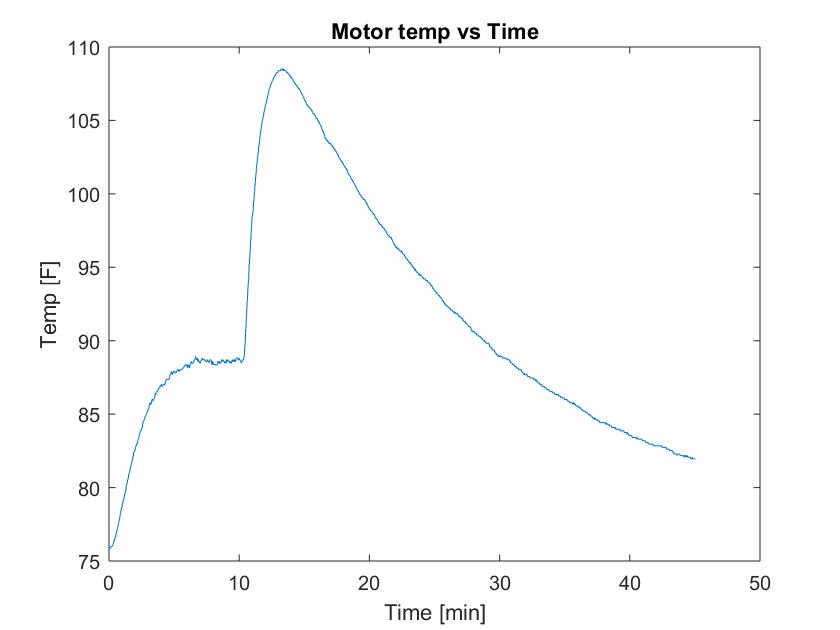

figure(1)
plot(time_m, Motor_Temp); title('Motor temp vs Time');
xlabel('Time [min]'); ylabel('Temp [F]');

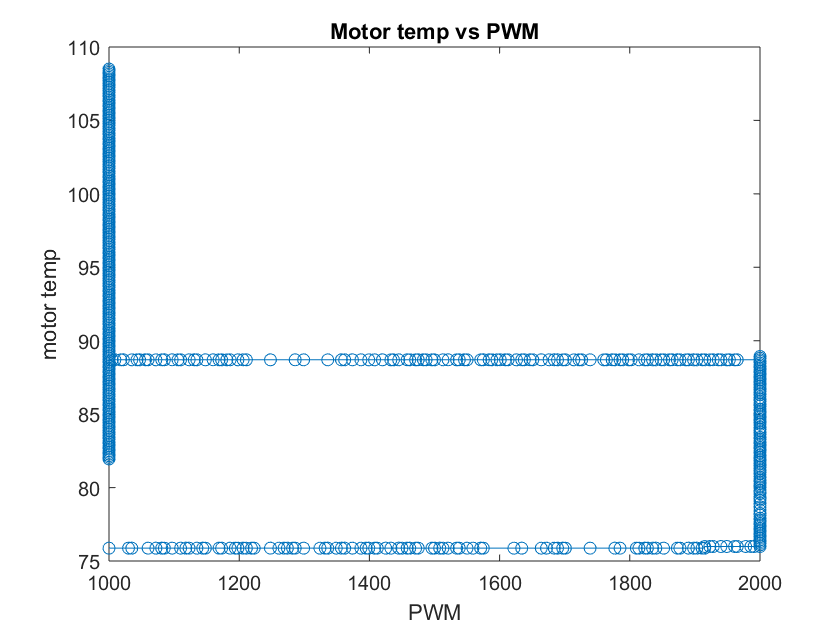


figure(2)
plot(PWM, Motor_Temp, 'o-'); title('Motor temp vs PWM')
xlabel('PWM'); ylabel('motor temp')

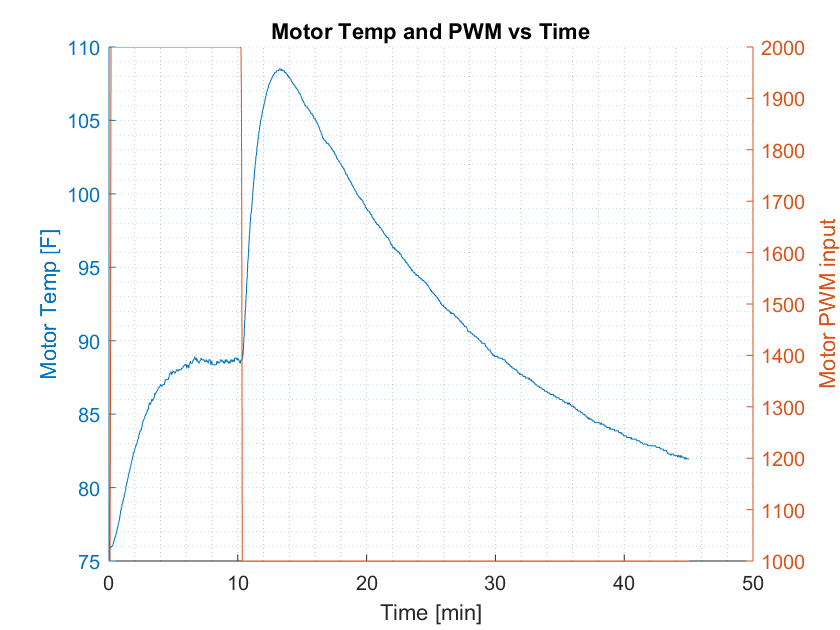


figure(3)
hold on
yyaxis left
plot(time_m, Motor_Temp);
ylim();
ylabel('Motor Temp [F]');
yyaxis right
plot(time_m, PWM);
ylabel('Motor PWM input');
title('Motor Temp and PWM vs Time');
xlabel('Time [min]');
grid('minor');
hold off

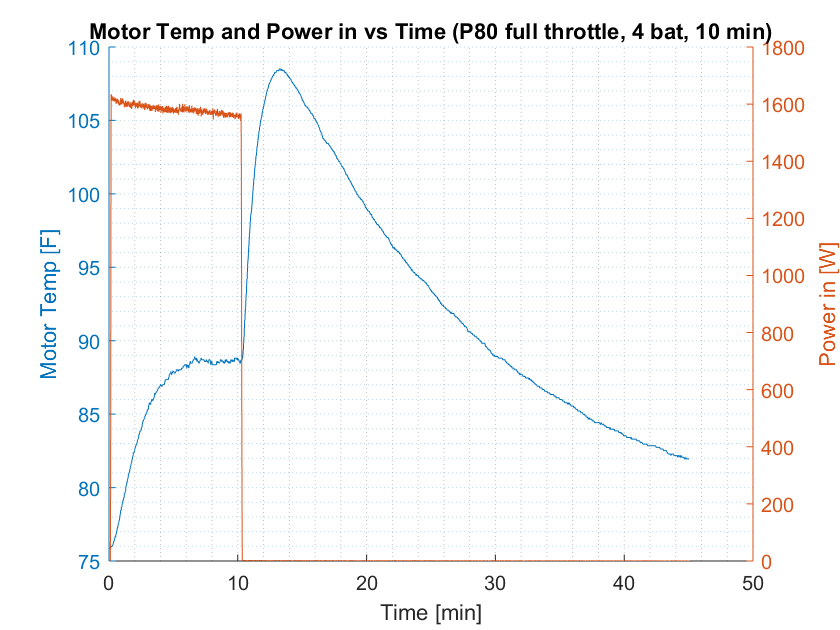


figure(4)
hold on
yyaxis left
plot(time_m, Motor_Temp);
ylim();
ylabel('Motor Temp [F]');
yyaxis right
plot(time_m, P_in_W);
ylabel('Power in [W]');
title('Motor Temp and Power in vs Time (P80 full throttle, 4 bat, 10 min)');
xlabel('Time [min]');
grid('minor');
hold off

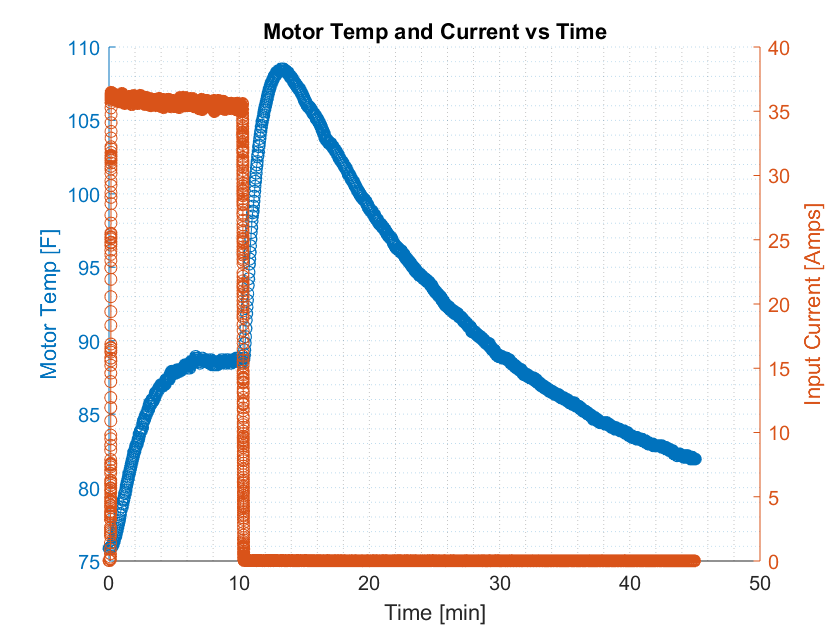


figure(5)
hold on
yyaxis left
plot(time_m, Motor_Temp, 'o-');
ylim([75 110]);
ylabel('Motor Temp [F]');
yyaxis right
plot(time_m, Input_A, 'o-');
ylabel('Input Current [Amps]');
title('Motor Temp and Current vs Time');
xlabel('Time [min]');
grid('minor');
hold off

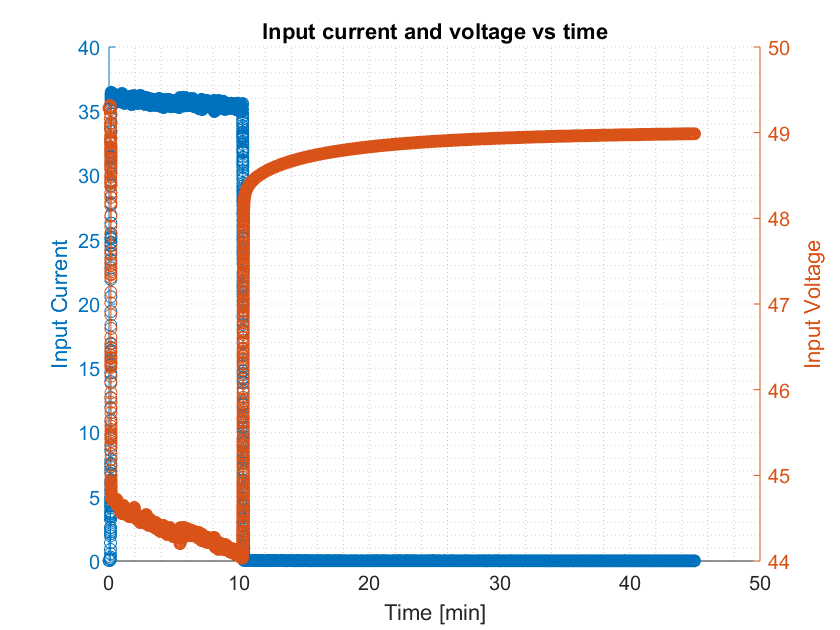


figure(6)
hold on
yyaxis left
plot(time_m, Input_A, 'o-');
ylabel('Input Current');
yyaxis right
plot(time_m, Input_V, 'o-');
ylabel('Input Voltage');
title('Input current and voltage vs time');
xlabel('Time [min]');
grid('minor');
hold off

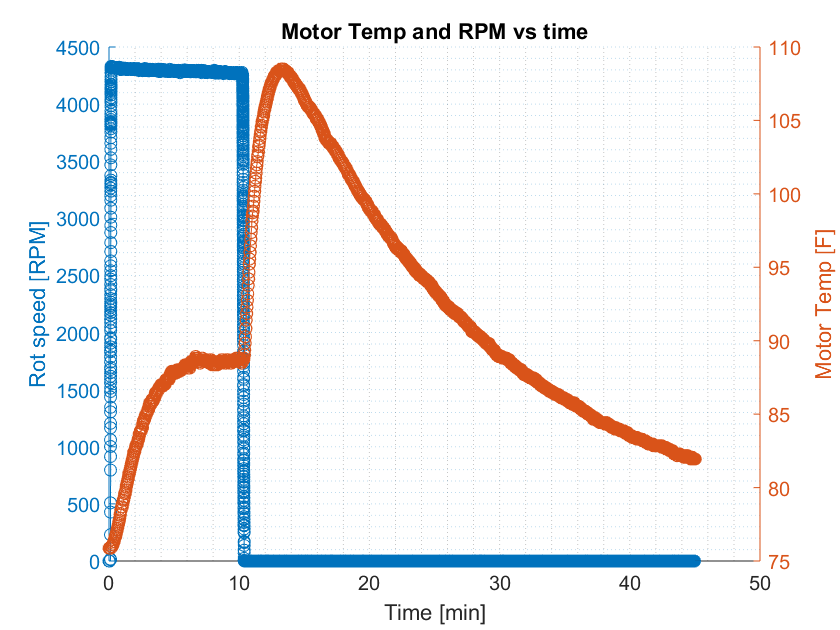


figure(7)
hold on
yyaxis left
plot(time_m, rot_speed_rpm, 'o-');
ylabel('Rot speed [RPM]');
yyaxis right
plot(time_m, Motor_Temp, 'o-');
ylabel('Motor Temp [F]');
title('Motor Temp and RPM vs time');
xlabel('Time [min]');
grid('minor');
hold off

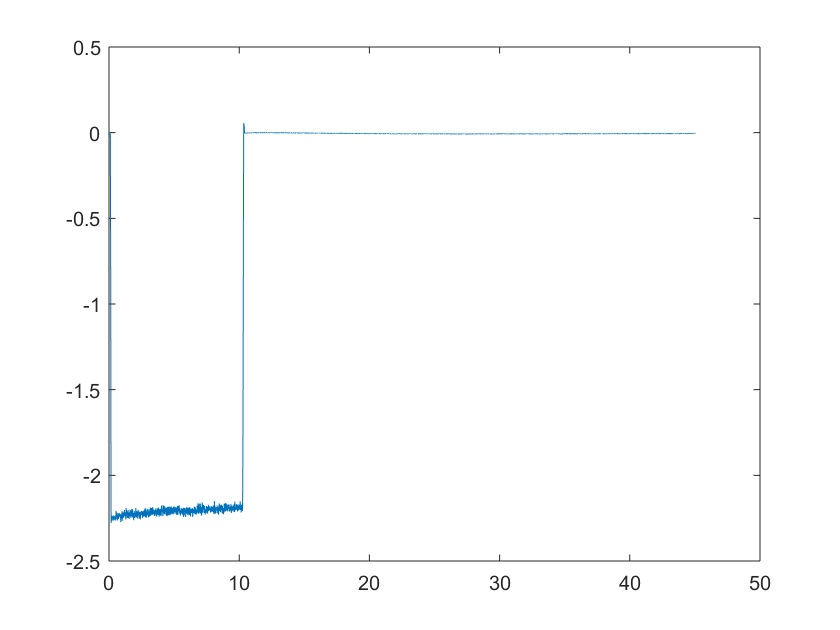


figure(8)
plot(time_m, Q)

## Comparing Data to Momentum Theory

k = 1.5;

C_T_theory = linspace(0, 0.01, 1000);

C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);

C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)

plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T, C_P, 'o-');

title('Comparison of Measured Data to Momentum Theory Calculations');

xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');

legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data')